# Discrete time models and discrete PID controller design in MATLAB

Control is commonly implemented in discrete time. In order to be able to analyse behaviour in discrete time the user needs some understanding of discrete time models and how these can be handled in MATLAB. 

Often discrete models can be treated using Z-transforms which MATLAB handles formally using tools in the control toolbox. The basic definition and usage of such discrete models is discussed in files ***discrete_models_and_usage.mlx***

***discretization_and_bode.mlx***

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A. Rossiter, University of Sheffield and  Ruth Bars and Gyula Max, Budapest University of Technology and Economics.

**Reference****: Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019**

                

## Table of contents

- Technical and mathematical background

- Pulse transfer functions of some basic elements

- Frequency function and BODE diagram of a sampled system

- Discrete PID controllers

- Design of PID controllers using pole cancellation

## 1.Technical and mathematical background

This file does not discuss details such as the zero-order-hold and sampler in detail.

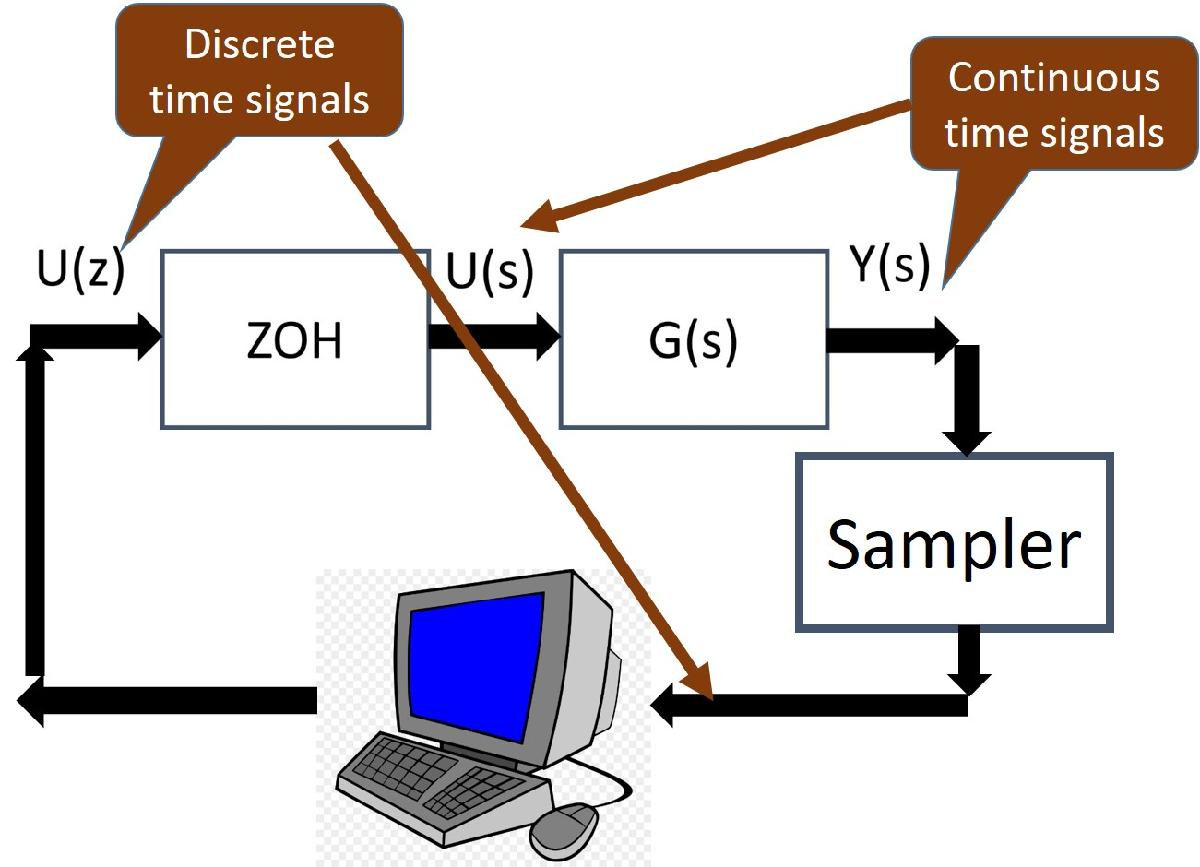

- The discretised system model *G(z)* (called also pulse transfer function) includes the ZOH (zero-order-hold) and sampler. 

- The compensator *M(z)* works entirely in discrete time (e.g. represented by the computer above).

A  z-transform model could be represented as:


$$\left(1+a\left(1\right)z^{-1} +a\left(2\right)z^{-2} +\cdots \right)y\left(k\right)=\left(b\left(1\right)z^{-1} +b\left(2\right)z^{-2} +\cdots \right)u\left(k\right)\;\Rightarrow Y\left(z\right)=\left\lbrack \frac{b\left(1\right)z^{-1} +b\left(2\right)z^{-2} +\cdots }{1+a\left(1\right)z^{-1} +a\left(2\right)z^{-2} +\cdots }\right\rbrack U\left(z\right)$$


This type of model equation can be used for both the system model *G(z)* and the compensator model *M(z)*. In general terms with a standard closed-loop we would deploy equations such as:


$$Y\left(z\right)=G\left(z\right)U\left(z\right)\;\;\;\;\;\;\;\;U\left(z\right)=M\left(z\right)\left\lbrack R\left(z\right)-Y\left(z\right)\right\rbrack$$
  

with $R\left(z\right)$ the target, $Y\left(z\right)$ the output and  $U\left(z\right)$ the input, $G\left(z\right)$ the system and $M\left(z\right)$ the compensator.

The assumption is made that the model may be first provided in continous time form, as most real systems are continuous. 

Sampling and holding introduces extra delay into the system, its value in between the half and the entire sampling time T.

The compensator is discrete, its output values are calculated in the sampling instants and the zero order hold ZOH provides the continuous input at the input of the process. 

The block diagram of the control system is given below.

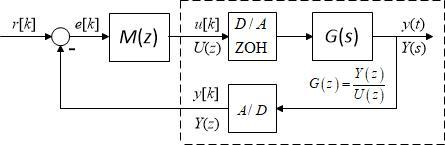 

## 2. Pulse transfer functions of some basic elements

Let us calculate the pulse transfer functions of some basic continuous elements in pole-zero zero form, assuming zero order hold.

The transfer function of a pure dead time (pure delay) element is $G\left(s\right)=e^{-sT_d }$. With sampling time T its pulse transfer function is $G\left(z\right)=z^{-k}$, where $k=\frac{T_d }{T}$.

The transfer function of a first order lag element is  $G\left(s\right)=\frac{1}{1+sT_1 }$  and the pulse transfer function supposing zero order hold is obtained as    $G\left(z\right)=\frac{1-e^{-\frac{T}{T_1 }} }{z-e^{-\frac{T}{T_1 }} }$.

The transfer function of a second order lag element is  $G\left(s\right)=\frac{1}{\left(1+sT_1 \right)\left(1+sT_2 \right)}$  and the pulse transfer function supposing zero order hold is obtained in form $G\left(z\right)=k\frac{z+\sigma }{\left(z-e^{-\frac{T}{T_1 }} \right)\left(z-e^{-\frac{T}{T_2 }} \right)}$. With 3 lags the pulse transfer function has 3 poles and 2 zeros.

The transfer function of an integrator is $G\left(s\right)=\frac{1}{s}$, its pulse transfer function is $\frac{T}{z-1}$.

#### 2.1 Example for calculation pulse transfer functions

disp('CONTINUOUS AND DISCRETE TRANSFER FUNCTIONS')
disp('First order lag element')
s=zpk('s')
G1=1/(1+0.1*s)
T=0.1           %sampling time
Gd1=c2d(G1,T)   %or alternatively Gd1=c2d(G1,T,'zoh'), discrete model
disp('Second order lag element')
G2=1/((1+0.1*s)*(1+0.2*s))
Gd2=c2d(G2,T)
[zerod2,poled2,kd2]=zpkdata(Gd2,'v') %extracting zeros and poles
disp('Third order lag element')
G3=1/((1+0.1*s)*(1+0.2*s)*(1+0.3*s))
Gd3=c2d(G3,T)
[zerod3,poled3,kd3]=zpkdata(Gd3,'v')
disp('Integrator')
G4=1/s
Gd4=c2d(G4,T)
clf
step(G1,G2,G3,Gd1,Gd2,Gd3) %step responses

## 3. Frequency function and BODE diagram of a sampled system

The frequency function of the pulse transfer function is obtained by substituting 

$z=e^{j\omega T}$, where T is the sampling time.

As an example let us consider the pulse transfer function and the frequency function of a first order lag element.

The transfer function is  $G\left(s\right)=\frac{1}{1+sT_1 }$  and the pulse transfer function supposing zero order hold is obtained as    $G\left(z\right)=\frac{1-e^{-\frac{T}{T_1 }} }{z-e^{-\frac{T}{T_1 }} }$. The frequency function is given as


$$G\left(z=e^{j\omega T} \right)=\frac{1-e^{-\frac{T}{T_1 }} }{e^{j\omega T} -e^{-\frac{T}{T_1 }} }\approx \frac{1-\left(1-\frac{T}{T_1 }+\frac{1}{2}{\left(\frac{T}{T_1 }\right)}^2 -\ldotp \ldotp \ldotp \right)}{1+j\omega T-\frac{{\left(\omega T\right)}^2 }{2}+\ldotp \ldotp \ldotp -\left(1-\frac{T}{T_1 }+\frac{1}{2}{\left(\frac{T}{T_1 }\right)}^2 -\ldotp \ldotp \ldotp \right)}$$


where the function is approximated by its Taylor series.

If  $T<T_1$ and $\omega T<1$  the higher powers of $\frac{T}{T_1 }$and $\omega T$ can be neglected and the frequency function of the sampled system is approximately the same as the frequency function of the continuous system.

$G\left(z=e^{j\omega T} \right)\approx \frac{1}{1+j\omega T_1 }e^{-j\omega T_a }$ where the neglected terms can be considered by the additional $T_a$ delay whose value is between the half and the entire sampling time. So the approximation is valid until $\omega =\frac{1}{T}$.

#### 3.1 Example comparing the Bode diagrams of a continuous and discrete first order system 

The transfer function is  $G\left(s\right)=\frac{1}{1+0\ldotp 1s}$, the sampling time is T=0.1 .

Determine the pulse transfer function and give the Bode diagrams of the continuous and the sampled systems between frequencies 0.1 and 100.

disp('COMPARING CONTINUOUS AND DISCRETE FREQUENCY FUNCTIONS')
s=zpk('s')
G=1/(1+0.1*s)
T=0.1
Gd=c2d(G,T)
w=logspace(-1,2,200);
[mags,phases]=bode(G,w);
[magd,phased]=bode(Gd,w);
disp('BODE DIAGRAMS')
subplot(211),loglog(w,mags(:),'b',w,magd(:),'r'),grid
phasewithdel=phases(:)-w'*(T/2)*180/pi;
subplot(212)
semilogx(w,phases(:),'b',w,phased(:),'r',w,phasewithdel,'g'),grid

It is seen that till $\omega =10$ the continuous and discrete amplitudes of the Bode amplitude diagram are almost coinciding, while in the phase angles a difference can be observed. Adding the phase coming from the half sampling time delay the phase angles become close to each other.

Remark: Therefore controller design for discrete systems can be based on frequency considerations for continuous systems.

## 4. Discrete PID controllers

The controller algorithms can be given immediately in discrete form by their transfer functions.                                             

The denominator of the pulse transfer functions of lag elements contain factors of form 


$$\left(z-e^{-\frac{T}{T_1 }} \right)\left(z-e^{-\frac{T}{T_2 }} \right)\ldotp \ldotp \ldotp$$


The controllers may apply so-called pole cancellation technique, cancelling the "bad" poles of the process and introducing "better" poles instead.

The discrete *P, PI, PD, PID* algorithms can be given by the following pulse transfer functions:

    P (proportional) controller:    *M*(*z*)=*A*

    PI controller:                        $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_1 }} }{z-1}$ ;    The biggest time constant of the process is cancelled

                                                                                     and an integrating effect is introduces instead.

    PD controller:                     $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_2 }} }{z-e^{-\frac{T}{T_2^* }} }$ ;     where  $T_2^*$<$T_2$.  An unfavourable time constant of the 

                                                                            process is cancelled and a instead a smaller time constant is

                                                                            introduced.

    Ideal PD controller:           $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_2 }} }{z}$ ;    The ideal differentiating effect in discrete form is

                                                                                   realizable, as the overexcitation is a finite value.                                            

    PIPD controller with ideal PD effect:

                            :                $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_1 }} }{z-1}\frac{z-e^{-\frac{T}{T_2 }} }{z}$

The gain of the controller can be designed to ensure a prescribed phase margin (e.g. ${60}^{\circ }$).

*Remark*: Instead of using parallel connected P, I and D controllers it is adviced to apply serially connected PI and PD controllers. This is advantageous in controller design.

The controllers are realized by their difference equations.

E.g. the difference equation of a PI controller is:

            
$$u\left\lbrack k\right\rbrack =\textrm{Ae}\left\lbrack k\right\rbrack -\textrm{Aexp}\left(-\frac{T}{T_1 }\right)e\left\lbrack k-1\right\rbrack +u\left\lbrack k-1\right\rbrack$$


The difference equation of the controller is a recursive relationship which can be realised in real time.  

*Remark*: Multiple *PI* and *PD* effects can also be applied if the limit given for the control signal *u *is not exceeded. 

#### **4.1 Step responses of the basic controllers** 

clf
subplot(111)
disp('STEP RESPONSE OF DISCRETE CONTROLLERS')
T=1             %sampling time
z=zpk('z',T)    %defining the z operator
disp('PI regulator')
Ti=10
A=2
pdi=exp(-T/Ti);
Mpi=A*(z-pdi)/(z-1)
step(Mpi,15)
disp('Ideal PD regulator')
Td=10
pdd=exp(-T/Td);
Mpd=A*(z-pdd)/z
step(Mpd,15)
disp('Non-Ideal PD regulator')
Td=10
Td1=1
pdd1=exp(-T/Td1);
Mpd1=A*(z-pdd)/(z-pdd1)
step(Mpd1,15),grid
disp('PIPD regulator')
Mpid=Mpi*Mpd/A
step(Mpid,15)

## 5. Design of PID controllers using pole cancellation

The controller is designed to ensure the quality specifications prescribed for the closed loop control system.

If the requirement is to track a step reference signal without steady state error, then an integrator should be included in the open loop transfer function. If the process model does not contain integrator, then an integrator should appear in the controller. 

With pole cancellation technique the unfavourable poles of the process can be cancelled by the zeros of the controller which introduces more favourable poles instead.

The gain of the controller is set to ensure ~60° phase margin, which corresponds to approximately 10% or less overshoot in the step response of the closed loop system. The phase margin is set on the basis of the frequency function of the open loop. A good approximation is that the cut-off frequency should be located approximately at $\omega_c \approx 1/\left\lbrack 2\left(T_d +T\right)\right\rbrack ,\;$where $T_d$ is the dead time and *T*  is the sampling time. The sampling time acts as an additional small dead time. Quick design can be made on the basis of the Bode amplitude diagram of the open loop of the continuous system, as it approximartes well the Bode diagram of the discrete system in the considered frequency range. 

The settling time of the output of the control system is approximated as $\frac{3}{\omega_c }<t_s <\frac{10}{\omega_c }$ . The higher is the cut-off frequency the faster is the process. But the dead time and the samping time give a limit for the acceleration. 

In practice the control signal (the manipulated variable) is restricted, its value should not exceed a given limit. This value should be checked. If it is exceeded then the design should be repeated, e.g. by increasing the prescribed phase margin.  

#### 5.1 Controller design for a third order proportional process

The continuous process is given by transfer function 

$G\left(s\right)=\frac{1}{\left(1+10s\right)\left(1+4s\right)\left(1+s\right)}$; The sampling time is T=1.

Design discrete P, PI, PD, PIPD controllers for 60° phase margin.

Show the step responses of the output and the control signal.

First give the transfer function and the pulse transfer function of the process.

s=zpk('s')                      %Give the s operator
G=1/((1+10*s)*(1+4*s)*(1+s))
T=1
Gd=c2d(G,T,'zoh')
[zd,pd,kd]=zpkdata(Gd,'v')      %Extracting the zero, pole and gain
z=zpk('z',T)                    %Give the z operator

The pulse transfer function is:


$$\textrm{Gd}\left(z\right)=\frac{0\ldotp 0030174\left(z+0\ldotp 188\right)\left(z+2\ldotp 712\right)}{\left(z-0\ldotp 9048\right)\left(z-0\ldotp 7788\right)\left(z-0\ldotp 3679\right)}$$


disp('THE CONTROLLERS WITH UNITY GAIN')
Ap=1;Api=1;Apd=1;Apid=1;
disp('Proportional controller')
Mp=1
disp('PI controller')
Mpi=(z-pd(1))/(z-1)
disp('ideal PD controller')
Mpd=(z-pd(2))/z
disp('PIPD controller')
Mpipd=Mpi*Mpd
disp('THE LOOP TRANSFER FUNCTIONS')
Lp=Gd
Lpi=minreal(Mpi*Gd,0.001)  %with command minreal the common factors
                           %in the numerator and denominator are cancelled
Lpd=minreal(Mpd*Gd,0.001)
Lpipd=minreal(Mpipd*Gd,0.001)
%
disp('CALCULATING THE GAINS OF THE CONTROLLERS')
%The frequency vector is given till 1/T=1
w=logspace(-2,0,200);
%
%Frequency function with the proportional controller
[mag,phase]=bode(Lp,w);
Table=[mag(:),phase(:),w']
%evaluate the table:The phase angle is -119.99° at w=0.2026. The gain here is 0.3365
%The cut-off frequency is located at this w value if the gain is Ap=1/0.3365
Mp=1/0.3365
Lp=Mp*Gd;
%check the phase margin
margin(Lp)
%Plot the output signal
step(Lp/(1+Lp)),grid
%Plot the control signal
step(Mp/(1+Lp)),grid
%
%Frequency function with the PI controller
[mag,phase]=bode(Lpi,w);
Table=[mag(:),phase(:),w']
%evaluate the table:The phase angle is -120° at w=0.0988. The gain here is 0.8905
%The cut-off frequency is located at this w value if the gain is Api=1/0.8905
Api=1/0.8905
Mpi=Api*Mpi;
Lpi=Api*Lpi;
%check the phase margin
margin(Lpi)
%Plot the output signal
step(Lpi/(1+Lpi)),grid
%Plot the control signal
step(Mpi/(1+Lpi)),grid
%
%Frequency function with the PD controller
[mag,phase]=bode(Lpd,w);
Table=[mag(:),phase(:),w']
%evaluate the table:The phase angle is -120° at w=0.3963. The gain here is 0.0497.
%The cut-off frequency is located at this w value if the gain is Apd=1/0.0497
Apd=1/0.0497
Mpd=Apd*Mpd;
Lpd=Apd*Lpd;
%check the phase margin
margin(Lpd)
%Plot the output signal
step(Lpd/(1+Lpd)),grid
%Plot the control signal
step(Mpd/(1+Lpd)),grid
%
%Frequency function with the PIPD controller
[mag,phase]=bode(Lpipd,w);
Table=[mag(:),phase(:),w']
%evaluate the table:The phase angle is -120° at w=0.2674. The gain here is 0.0756.
%The cut-off frequency is located at this w value if the gain is
%Apid=1/0.0756
Apid=1/0.0756
Mpipd=Apid*Mpipd;
Lpipd=Apid*Lpipd;
%check the phase margin
margin(Lpipd)
%Plot the output signal
step(Lpipd/(1+Lpipd)),grid
%Plot the control signal
step(Mpipd/(1+Lpipd)),grid
%
Tp=Lp/(1+Lp);Tpi=Lpi/(1+Lpi);Tpd=Lpd/(1+Lpd);Tpipd=Lpipd/(1+Lpipd);
step(Tp,Tpi,Tpd,Tpipd),grid
title('THE STEP RESPONSES OF THE SYSTEM WITH P, PI, PD, PID CONTROLLERS')


It can be seen that with P and PD controllers there is a static error in steady state. PD and PIPD controllers provide faster behaviour on the price of higher actuating control signals.

*Remark*: The output values are calculated only in the sampling points.The plot command connects these points with horizontal line. To get the output values of the continuous system between the sampling points it is necessary to calculate these inner values or to use simulink program.

#### 5.2 Controller design for a dead time process

The continuous system is given by a first order lag element with significant dead time.

Its transfer function is

$G\left(s\right)=\frac{1}{1+4s}e^{-8s}$ . The sampling time is T=2.

Design a discrete PI controller ensuring approximately 60° phase margin.

The cut-off frequency should be approximately at $\frac{1}{2\left(8+2\right)}$=0.05

disp('CONTROLLER DESIGN FOR A FIRST ORDER LAG ELEMENT WITH DEAD TIME')
s=zpk('s');
T=2
z=zpk('z',T);
disp('The continuous system')
G=1/(1+4*s)
Td=8
Gd=c2d(G,T,'zoh');
[zd,pd,kd]=zpkdata(Gd,'v');
disp('The discrete system')
Gdd=Gd*z^-4
%The PI controller
Md=(z-pd(1))/(z-1);
Ld=minreal(Md*Gdd,0.001);
%The frequency function 
w=logspace(-3,0,200);
[mag,phase]=bode(Ld,w);
disp('The frequency function: amplitude, phase, frequency')
Table=[mag(:),phase(:),w']
%evaluate the table:The phase angle is -120° at w=0.0581. The gain here is 3.39.
%The cut-off frequency is located at this w value if the gain is A=1/3.39=0.294
disp('The controller')
Md1=Md*0.294
Ld1=Ld*0.294;
%Check the phase margin
margin(Ld1)
Cl=Ld1/(1+Ld1);
Cl=minreal(Cl,0.001);
%The output signal
disp('The output signal')
step(Cl)
Ud=Md1/(1+Ld1);
Ud=minreal(Ud,0.001);
%The control signal
disp('The control signal')
step(Ud)


*Remark*: The dead time restricts the acceleration of the closed loop system. The settling process with PID controllers is slow.